%This method converts an uncorrelated Gaussian sequence to a correlated Gaussian process. 
%The method of filters is used to modify the incoming white process. 
%The PSD of target correlated signal is used to develop the frequency
%response of the filter

%This function gets the impulse response of the reqired filter which can
%then be convolved with our white Gaussian process to get the target signal
function [hw] = Jakes_filter(f_max,Ts,N)
L=N/2;
n=1:L;
J_pos=besselj(0.25,2*pi*f_max*n*Ts)./(n.^0.25);
J_neg = fliplr(J_pos);
J_0 = 1.468813*(f_max*Ts)^0.25;
J = [J_neg J_0 J_pos]; %Jakes filter

%Now window the filter using Hamming window
n=0:N; 
hamm = 0.54-0.46*cos(2*pi*n/N); 
hw = J.*hamm;

%Normalized impulse response
hw = hw./sqrt(sum(abs(hw).^2));

end

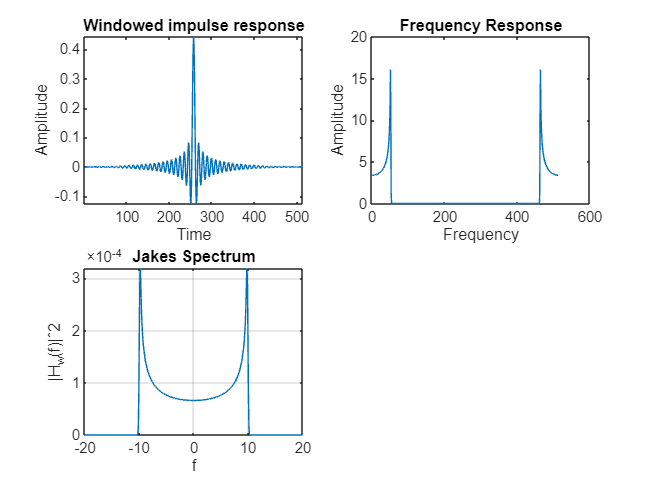

fd=10; %maximum Doppler frequency
Fs=100;%sampling frequency
N=512;%order of Jakes filter
Ts=1/Fs;%sampling interval
[h] = Jakes_filter(fd,Ts,N);%design Jakes filter

%White Gaussian Process input
x = randn(1,1000); 
y = conv(x,h,'valid');

%Plots
%Impulse Response in Time domain
figure;
subplot(2, 2, 1); 
plot(h); 
axis tight;
title('Windowed impulse response');
xlabel('Time'); 
ylabel('Amplitude');

%Frequency Response
subplot(2, 2, 2);
plot(abs(fft(h)).^2);
xlabel('Frequency');
ylabel('Amplitude');
title('Frequency Response');

%Jakes Spectrum - PSD of signal y or square of Frequency Response
subplot(2, 2, 3);
num1 = 2^nextpow2(length(h));
freq1 = fftshift(fft(h, num1));
fVals = (1/Ts)*(-num1/2:num1/2-1)/num1;
H_w = (Ts/length(h))*abs(freq1).^2;
plot(fVals,H_w); 
grid on; 
xlim([-20 20]);
title('Jakes Spectrum');
xlabel('f');
ylabel('|H_{w}(f)|ˆ2');

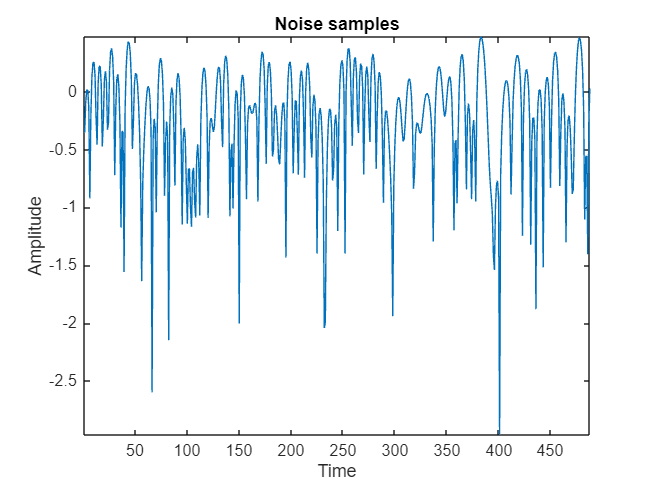

%Output signal y
figure;
plot(log10(abs(y))); 
hold on;
axis tight; 
xlabel('Time'); 
ylabel('Amplitude');
title('Noise samples');

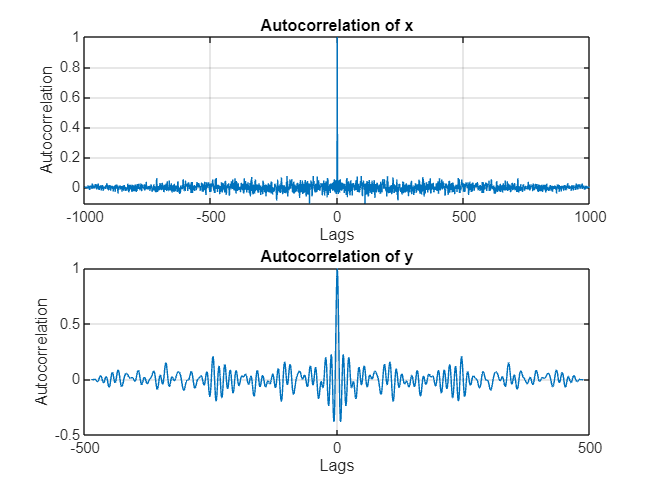

[autocorr_x, lags_x] = xcorr(x, 'normalized');
[autocorr_y, lags_y] = xcorr(y, 'normalized');

% Plot the autocorrelation of x
figure;
subplot(2,1,1);
plot(lags_x, autocorr_x);
title('Autocorrelation of x');
xlabel('Lags');
ylabel('Autocorrelation');
grid on;

% Plot the autocorrelation of y
subplot(2,1,2);
plot(lags_y, autocorr_y);
title('Autocorrelation of y');
xlabel('Lags');
ylabel('Autocorrelation');
grid on;